interval = [0,10]

interval =      0    10


left = interval(1,1)

left = 0

right = interval(1,2)

right = 10

e = 10.^-4

e = 1.0000e-04

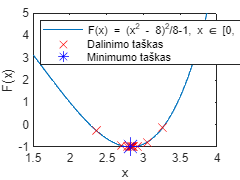

 
[debugArray, cutCount, L] = gold_div(e, left, right);
x = 1.5:0.01:4;
f = givenFunction(x);

plot(x, f);
hold on;
plot(debugArray(:, 1), debugArray(:, 2), "xr", 'MarkerSize', 9);
plot(debugArray(end, 1), debugArray(end, 2), 'b*', 'MarkerSize', 14);
legend(["F(x) = (x^2 - 8)^2/8-1, x ∈ [0, 10]", "Dalinimo taškas", "Minimumo taškas"], "location","northwest");
ylim([-1 5])
xlim([1.5 4])
ylabel("F(x)")
xlabel("x")
hold off;


disp("Loops: " + cutCount + ";")

Loops: 24;


disp("Main function called: " + length(debugArray) + " times.")

Main function called: 26 times.


disp("Last f(x) value: " + debugArray(length(debugArray), 2))

Last f(x) value: -1


%givenFunction = @(x) (x.^2 - a).^2 /b -1
function f = givenFunction(x)
    a = 8;
    b = 8;
    f = (x.^2 -a).^2 /b -1;
end

% Auksinis pjuvis
function [debugArray, cutCount, L] = gold_div(e, left, right)
    t = (-1 + 5.^0.5)/2;
    L = right - left;
    cutCount = 0;

    x1 = right - t*L;
    x2 = left + t*L;

    y1 = givenFunction(x1);
    debugArray = [x1, y1];

    y2 = givenFunction(x2);
    debugArray = cat(1, debugArray, [x2, y2]);

    while L > e
        if(y2 < y1)
            left = x1;
            x1 = x2;
            y1 = y2;
            L = right - left;
            x2 = left + t*L;
            y2 = givenFunction(x2);
            debugArray = cat(1, debugArray, [x2, y2]);
        elseif(y1 < y2)
            right = x2;
            L = right - left;
            x2 = x1;
            y2 = y1;
            x1 = right - t*L;
            y1 = givenFunction(x1);
            debugArray = cat(1, debugArray, [x1, y1]);
        else
            left = x1;
            right = x2;
            % to do

        end
        cutCount = cutCount + 1;
    end
end

% turi y nueiti i -1
% x - saknis is 8